Let's start by fixing the path

clear
clc

full_path='D:\MATLAB AP Package Beta\';
project_path='D:\MATLAB AP Package Beta\Scratch\Week 6\';

addpath(genpath([full_path,'Data\']));
addpath(genpath([full_path,'Functions\']));
addpath(genpath(project_path));
cd(project_path);

clear full_path project_path  


## Effective spread measures figures replications:

The coding exercise asked you to replicate one of three figures in papers proposing effective spread estimates. The first of those was Hasbrouck's (2009) Figure 3, Panel A


clear
clc

load pdates
load dates
load exchcd
load me
load effSpreadStruct
load NYSE

set(0,'DefaultAxesFontName', 'Times New Roman')

axisSize   = 15;
lineWidth  = 3;
markerSize = 3;

veryLightGray = [0.77,0.77,0.77];
lightGray     = [0.66,0.66,0.66];
darkGray      = [0.33,0.33,0.3];
veryDarkGray  = [0.22,0.22,0.22];


f = figure; 

for thisExchCode = 1:3
        
    subplot(3, 1, thisExchCode);
    
    gibbs = effSpreadStruct.gibbs/2;
    
    indExchToExcl = exchcd ~= thisExchCode | isnan(gibbs);
    gibbs(indExchToExcl) = nan;
    
    decIndicator = dates-100*floor(dates/100)==12;
    me(~decIndicator, :)    = nan;
    gibbs(~decIndicator, :) = nan;
    
    indME4 = makeUnivSortInd(me, 4, NYSE);
    
    y = [];
    for i = 1:4
        quartileI = gibbs;
        quartileI(indME4~=i) = nan;
        y = [y mean(quartileI, 2, 'omitnan')];
    end
    
    
    pdates = pdates-0.5;
    x = floor(dates/100);
        
    ind = isfinite(x + sum(y,2));
    x = x(ind);
    y = y(ind, :);
    
    hold on;
    plot(x, y(:,1),'LineStyle', '-',  'color', veryLightGray, 'LineWidth', lineWidth)
    plot(x, y(:,2),'LineStyle', '-.', 'color', lightGray,     'LineWidth', lineWidth, 'MarkerSize', markerSize)
    plot(x, y(:,3),'LineStyle', '-',  'color', darkGray,      'LineWidth', lineWidth, 'MarkerSize', markerSize)
    plot(x, y(:,4),'LineStyle', '--', 'color', veryDarkGray,  'LineWidth', lineWidth, 'MarkerSize', markerSize)
    hold off;
    set(gca, 'FontSize', axisSize);
    ylabel('Effective spread', 'FontSize', axisSize);
    legend('Quartile 1','Quartile 2','Quartile 3','Quartile 4');

    
    if thisExchCode == 1        
        ylim([0 0.10]);
        title('Panel A. NYSE');
    elseif thisExchCode == 2
        ylim([0 0.05]);
        title('Panel B. AMEX');
        xlim([1960 2021]);
    else
        ylim([0 0.05]);
        title('Panel C. NASDAQ');
        xlim([1985 2021]);        
    end
end

scr_siz = get(0,'ScreenSize') ;
f.Position = floor([1 1 scr_siz(3)/3 scr_siz(4)*.9]);

Compare this with:

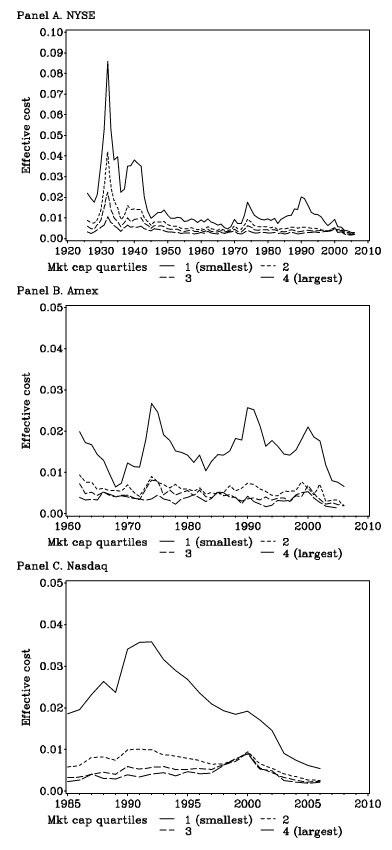

It should not be very surprising that they are close. We have used Hasbrouck's own code after all. 

Let's do Corwin and Schultz Figure 2 next:

clear
clc

load pdates
load dates
load exchcd
load me
load effSpreadStruct
load NYSE

set(0,'DefaultAxesFontName', 'Times New Roman')

axisSize   = 15;
lineWidth  = 3;
markerSize = 3;

veryLightGray = [0.77,0.77,0.77];
lightGray     = [0.66,0.66,0.66];
darkGray      = [0.33,0.33,0.3];
veryDarkGray  = [0.22,0.22,0.22];



hl = effSpreadStruct.hl;

indExchToExcl = exchcd~=1 & exchcd~=2;
me(indExchToExcl) = nan;
hl(indExchToExcl) = nan;

indME10 = makeUnivSortInd(me, 10);
small = hl;
small(indME10~=1)  = nan;
large = hl;
large(indME10~=10) = nan;


pdates = pdates-0.5;

y = [mean(hl, 2, 'omitnan') ...
    mean(small, 2, 'omitnan') ...
    mean(large, 2, 'omitnan')];
x = pdates;

f = figure; 

subplot (2, 1, 1);
b = find(dates==192601);
e = find(dates==200612);

hold on;
plot(x,y(:,1), 'LineStyle', '-',  'color', veryDarkGray, 'LineWidth', lineWidth)
plot(x,y(:,2), 'LineStyle', '-.', 'color', darkGray,     'LineWidth', lineWidth, 'MarkerSize', markerSize)
plot(x,y(:,3), 'LineStyle', '-',  'color', darkGray,     'LineWidth', lineWidth, 'MarkerSize', markerSize)
legend('NYSE','Small Stocks','Large Stocks');
xlim([pdates(b) pdates(e)])
ylim([0 nanmax(nanmax(y(b:end,:)))+0.01]);
set(gca,'FontSize',axisSize);
hold off;


subplot (2, 1, 2);
b = find(dates==195001);
e = find(dates==200612);

hold on;
plot(x,y(:,1), 'LineStyle', '-',  'color', veryDarkGray, 'LineWidth', lineWidth)
plot(x,y(:,2), 'LineStyle', '-.', 'color', darkGray,     'LineWidth', lineWidth, 'MarkerSize', markerSize)
plot(x,y(:,3), 'LineStyle', '-',  'color', darkGray,     'LineWidth', lineWidth, 'MarkerSize', markerSize)
xlim([pdates(b) pdates(e)])
ylim([0 nanmax(nanmax(y(b:end,:)))+0.01]);
set(gca,'FontSize',axisSize);
hold off;

scr_siz = get(0,'ScreenSize') ;
f.Position = floor([1 1 scr_siz(3)/3 scr_siz(4)*.9]);

Compare with:

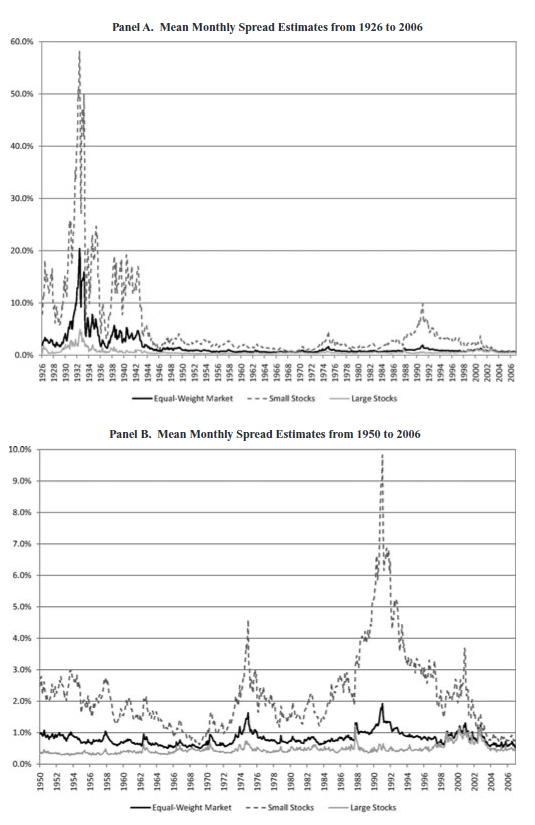

Now let's do Figure 8 from Abdi and Ranaldo (2017)

clear
clc

load pdates
load dates
load exchcd
load me
load effSpreadStruct
load NYSE

set(0,'DefaultAxesFontName', 'Times New Roman')

axisSize   = 15;
lineWidth  = 3;
markerSize = 3;

veryLightGray = [0.77,0.77,0.77];
lightGray     = [0.66,0.66,0.66];
darkGray      = [0.33,0.33,0.3];
veryDarkGray  = [0.22,0.22,0.22];

f = figure; 

subplot (2, 1, 1);

b = find(dates==192601);
e = find(dates==200612);

chl = effSpreadStruct.chl;
tempMe = me;

indExchToExcl = exchcd~=1;
tempMe(indExchToExcl) = nan;
chl(indExchToExcl) = nan;

indME10 = makeUnivSortInd(tempMe, 10);
small = chl;
small(indME10~=1)  = nan;
large = chl;
large(indME10~=10) = nan;

y = [mean(chl, 2, 'omitnan') ...
    mean(small, 2, 'omitnan') ...
    mean(large, 2, 'omitnan')];
x = pdates-0.5;

hold on;
plot(x, y(:,1), 'LineStyle', '-',  'color', veryDarkGray, 'LineWidth', lineWidth)
plot(x, y(:,2), 'LineStyle', '-.', 'color', darkGray,     'LineWidth', lineWidth, 'MarkerSize', markerSize)
plot(x, y(:,3), 'LineStyle', '-',  'color', darkGray,     'LineWidth', lineWidth, 'MarkerSize', markerSize)
legend('NYSE','Small Stocks','Large Stocks');
xlim([pdates(b) pdates(e)])
ylim([0 nanmax(nanmax(y(b:end,:)))+0.01]);
set(gca,'FontSize', axisSize);
title('NYSE stocks', 'FontSize', axisSize);
hold off;


subplot (2, 1, 2);

b = find(dates==196301);
e = find(dates==200612);

chl = effSpreadStruct.chl;
tempMe = me;

indExchToExcl = exchcd~=2;
tempMe(indExchToExcl) = nan;
chl(indExchToExcl) = nan;

indME10 = makeUnivSortInd(tempMe, 10);
small = chl;
small(indME10~=1)  = nan;
large = chl;
large(indME10~=10) = nan;

y = [mean(chl, 2, 'omitnan') ...
    mean(small, 2, 'omitnan') ...
    mean(large, 2, 'omitnan')];
x = pdates-0.5;


hold on;
plot(x, y(:,1), 'LineStyle', '-',  'color', veryDarkGray, 'LineWidth', lineWidth)
plot(x, y(:,2), 'LineStyle', '-.', 'color', darkGray,     'LineWidth', lineWidth, 'MarkerSize', markerSize)
plot(x, y(:,3), 'LineStyle', '-',  'color', darkGray,     'LineWidth', lineWidth, 'MarkerSize', markerSize)
xlim([pdates(b) pdates(e)])
ylim([0 nanmax(nanmax(y(b:end,:)))+0.01]);
set(gca,'FontSize', axisSize);
title('AMEX stocks', 'FontSize', axisSize);
hold off;

scr_siz = get(0,'ScreenSize') ;
f.Position = floor([1 1 scr_siz(3)/3 scr_siz(4)*.9]);

Compare with:

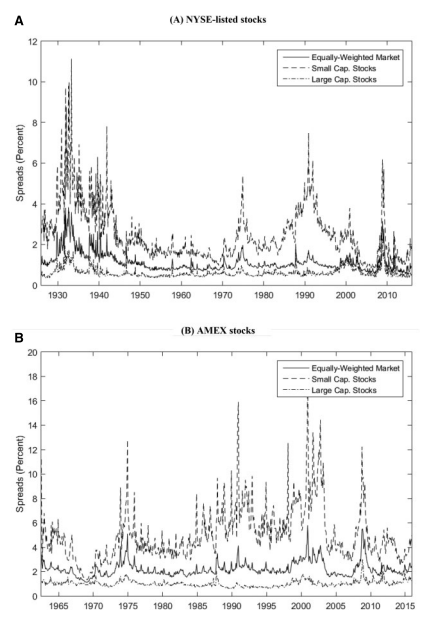

## Using trading costs:

To replicate the net return results from Novy-Marx and Velikov (2016) is quite easy. The use_library.m file shows you this:

clear
clc

load dates
load me
load ret
load NYSE
load gibbs_filled

% Read the signals data
[anoms23, labels23] = getAnomalySignals('novyMarxVelikovAnomalies.csv', 1, 2);
% [anoms23, labels23] = getAnomalySignals('novyMarxVelikovAnomalies.csv', 'permno', 'dates');

% Store the number of anomalies and the start dates
nAnoms = size(anoms23, 3);
startDate = [1 1 1 1 1 1 1 1 2 2 2 1 1 1 1 2 2 1 1 1 1 1 1]; % 1 - 196306, 2 - 197306
startDate(startDate==1) = 196306;
startDate(startDate==2) = 197306;

for i = 1:nAnoms
    ind = makeUnivSortInd(anoms23(:,:,i), 10, NYSE);
    ind = 1*(ind==1) + 2*(ind==10);
    res = runUnivSort(ret, ind, dates, me, 'tcosts', tcosts, ...
                                           'timePeriod', [startDate(i) 201212], ...
                                           'plotFigure', 0, ...
                                           'printResults', 0); 
    coefs(i,:)  = [res.xret(end) res.alpha(end) res.turnover 100*res.tcosts res.netxret];
    tstats(i,:) = [res.txret(end) res.talpha(end) nan nan res.tnetxret];
end

mat2Tex(coefs, tstats, labels23, 2)

Compare those with:

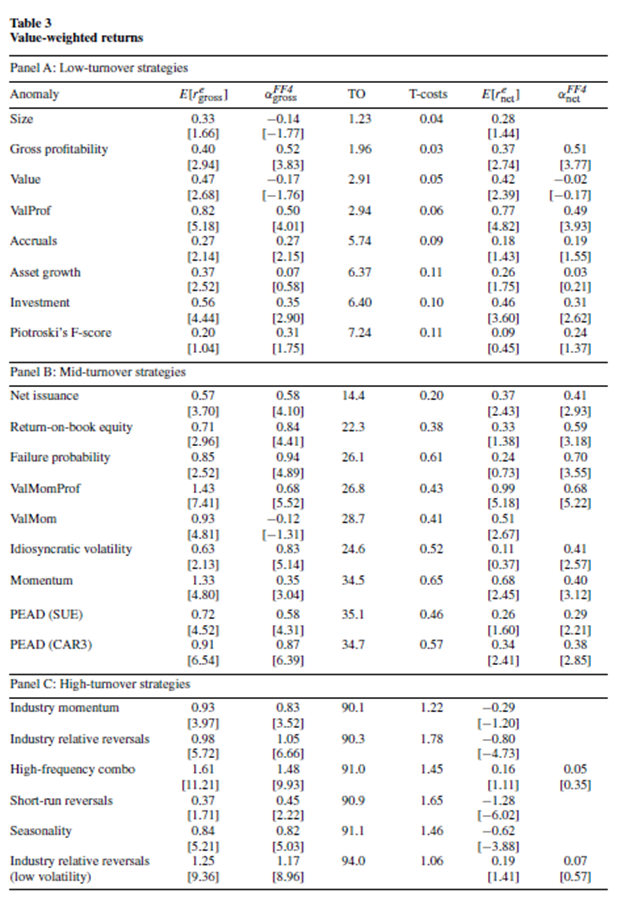

To save on time, let's just run it for a few anomalies:

clear
clc

load dates
load me
load ret
load NYSE
load gibbs_filled
load ff

% Pick the anomaly signals. These need to match the column names in the .csv file
anomalyNames = {'momentum','peadSUE','peadCAR3'};
[anoms, labels] = getAnomalySignals('novyMarxVelikovAnomalies.csv', 'permno', 'dates', ...
                                                                    'anomalyNames', anomalyNames);


ind = makeUnivSortInd(anoms(:, :, 1), 10, NYSE);
ind = 1*(ind==1) + 2*(ind==10);
res = runUnivSort(ret, ind, dates, me, 'tcosts', tcosts, ...
                                       'timePeriod', [196306 201212], ...
                                       'plotFigure', 0); 
fprintf('\n\nGross average return [t-stat]: %0.2f [%1.2f].\n\n', res.xret(end), res.txret(end));
fprintf('\nNet average return [t-stat]: %0.2f [%1.2f].\n\n', res.netxret, res.tnetxret);


But how did we get the net return? The anomaly trading strategy has a long and a short side. We need to get the returns for both of those. 

Let's replicate the gross return first:

lMe = lag(me, 1, nan);
lInd = lag(ind, 1, 0);
longGrossRet = sum(ret .* lMe .* (lInd==2), 2, 'omitnan') ./ sum(lMe .* (lInd==2), 2, 'omitnan');
shortGrossRet = sum(ret .* lMe .* (lInd==1), 2, 'omitnan') ./ sum(lMe .* (lInd==1), 2, 'omitnan');
longShortGrossRet = longGrossRet - shortGrossRet;

s = find(dates == 196307);
e = find(dates == 201212);

prt(nanols(longGrossRet(s:e) - shortGrossRet(s:e), const(s:e)));

Now let's get the trading costs. We need to do that for both portfolios. For each portfolio, we need to figure out how much trading we need to do each month, and multiply the change in weights by the effective half-spreads:


$${\textrm{TC}}_{t\;} =\sum_{i=1}^{N_{t\;} } |w_{i,t} -\tilde{\;w_{i,t} } |\cdot c_{i,t}$$


where $w_{i,t}$ is the weight of stock $i$ at time $t$ after rebalancing, and $\tilde{\;w_{i,t} } =w_{i,t-1} \times \left(1+r_{i,t} \right)$ is the weight of the stock $i$ at time $t$ before rebalancing.

The calculation will also make a few simplifying assumptions:

- We'll use the growth in market capitalization to determine the weights before rebalancing

- We'll assume that we rebalance to hold $1 in each leg of the portfolio at each rebalancing period. That is, we won't allow the total amont invested to grow over time. 

- We'll ignore any transaction costs associated with potential dividend reinvestments.

Let's start with the long side:

nStocks = size(me, 2);
gretxd = me./lag(me, 1, nan); % gross ret ex-div

totalMe = sum(me .* (ind == 2), 2, 'omitnan');
Wout = (me .* (ind == 2)) ./ repmat(totalMe, 1, nStocks);
Win = lag(Wout, 1, 0) .* gretxd;                     

dW = Wout - Win;                                    
dW(dW == 0) = nan;

costsLong = sum(abs(dW) .* tcosts, 2, 'omitnan');

Now on the short side:

totalMe = sum(me .* (ind == 1), 2, 'omitnan');
Wout = (me .* (ind == 1)) ./ repmat(totalMe, 1, nStocks);
Win = lag(Wout, 1, 0) .* gretxd;                     

dW = Wout - Win;                                    
dW(dW == 0) = nan;

costsShort = sum(abs(dW) .* tcosts, 2, 'omitnan');

Add both of these and adjust the returns to get the net returns

costs = costsLong + costsShort;
netRets = longShortGrossRet - costs;
prt(nanols(netRets(s:e) , const(s:e)));

Compare with:

fprintf('\nNet average return [t-stat]: %0.2f [%1.2f].\n\n', res.netxret, res.tnetxret);

## Performance evaluation accounting for transaction costs

Novy-Marx and Velikov (2016) points out that in the presence of trading costs, we can't use a basic regression to evaluate whether a new asset improves the investment frontier relative to a set of base assets:

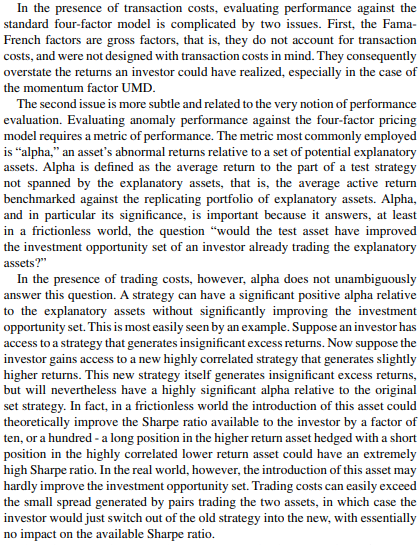

clear
clc

load dates
load me
load ret
load NYSE
load gibbs_filled
load ff
load ff_tc
load R

% Pick the anomaly signals. These need to match the column names in the .csv file
anomalyNames = {'valMom'};
[anoms, labels] = getAnomalySignals('novyMarxVelikovAnomalies.csv', 'permno', 'dates', ...
                                                                    'anomalyNames', anomalyNames);


ind = makeUnivSortInd(anoms(:, :, 1), 10, NYSE);
ind = 1*(ind==1) + 2*(ind==10);
res = runUnivSort(ret, ind, dates, me, 'tcosts', tcosts, ...
                                       'plotFigure', 0); 

% Check out the net ret 
s = find(dates==196307);
e = find(dates==201212);

anomRet = res.pret(s:e, end);
anomTcosts = res.tcostsTS(s:e);

factorRets = ff4(s:e, 2:end);
factorTcosts = [zeros(e-s+1, 1) smb_tc(s:e) hml_tc(s:e) umd_tc(s:e)];

prt(nanols(anomRet - anomTcosts,[const(s:e) factorRets - factorTcosts]));

See a problem with that?

The generalized alpha solves this by using the mean-variance efficient (MVE) portfolios. The generalized alpha is defined as the alpha in the following regression: 


$$w_{y\;}^{-1} \;R_{\mathrm{MVE}\left(X,y\right)} =\alpha +\beta \;R_{\mathrm{MVE}\left(X\right)} +\varepsilon \;$$


where $\textrm{MVE}\left(X,y\right)$ denotes the mean-variance efficient portfolio of a set of base assets,$X$, and a test asset,$\;y$; $\textrm{MVE}\left(X\right)$ denotes the mean-variance efficient portfolio of the set of base assets,$X$; and $w_{y\;}^{-1}$ is the weight of y in $\textrm{MVE}\left(X,y\right)$.

The alpha is defined to be zero if $w_{y\;}^{-1} =0$, and the scaling is there, so that this alpha agrees with common notion of alpha in the absence of trading costs. Let's see what this looks like in the data:

[alpha_res, w_X_y, w_X] = calcGenAlpha(anomRet, anomTcosts, factorRets, factorTcosts, 0);

Let's now zoom in on the actual estimation of the MVEs. Without trading costs, the weights in the $\textrm{MVE}\left(X\right)$ can be calculated using the standard formula:


$$w=\frac{\Sigma {\;}^{-1} \mu_{e\;} \;}{1^{\prime } \Sigma {\;}^{-1} \mu_{e\;} \;}$$


The code allows that using the calcMve() function:

 [grossFF4Weights, FF4MVESharpe] = calcMve(factorRets) 

With net returns, however, this breaks down. The math doesn't quite work out because you need to subtract trading costs even when you short. The code has a function that does that for factors called calcNetMve(). The calcGenAlpha() function basically uses the calcNetMve() function with and without the test asset. However, the calcNetMve() function takes as inputs both  the long and short version of the assets. Footnote 4 in Novy-Marx and Velikov (2016) explains why:

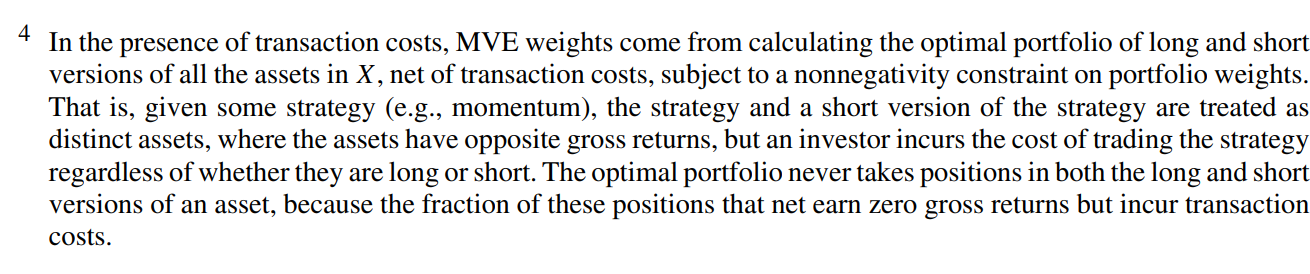

More formally (coming from Detzel, Novy-Marx, and Velikov, JF R&R), suppose you have K test assets with gross returns given by:


$$r_t =\left(r_{1t} ,r_{2t} ,\ldotp \ldotp \ldotp ,r_{\textrm{Kt}} \right)$$


The net long return on the $k^{\textrm{th}}$ asset is given by: 


$$r_{\textrm{kt}}^{L,\textrm{net}} =r_{\textrm{kt}} -{\textrm{TC}}_{t\;}^{r_k }$$
 

where ${\textrm{TC}}_{t\;}^{r_k }$ is the trading cost of the asset in the current month.

The corresponding short return is given by:


$$r_{\textrm{kt}}^{S,\;\textrm{net}} ={-r}_{\textrm{kt}} -{\textrm{TC}}_{t\;}^{r_k }$$


Then, letting $r_t^{\textrm{net}}$ denote $2K$ vector of both the long and short factor returns, $\mu =E\left(r^{\textrm{net}\;} \right)$ and $\Sigma =\textrm{Cov}\left(r^{\textrm{net}} \right)$, the MVE weights accounting for transaction costs are given by the solution for $\theta \;$in the following problem:


$$\max_{\theta \;\in {\mathit{\mathbf{R}}}^{2K} \;}$$

$${\left(\frac{\theta {\;}^{\prime } \mu \;}{\sqrt{\theta^{\prime } \Sigma \;\theta \;\;}\;}\right)}^{2\;}$$


subject to $\theta_k \ge 0\;\forall \;k$ and $\Sigma {\;}_k \;\theta {\;}_k =1$

Intuitively, this is equivalent to finding the mean-variance efficient portfolio of assets the replicate the long and short positions of each factor. If trading costs are zero, this is equivalent to finding the maximum squared Sharpe ratio of the gross factors without the nonnegativity contraints on the weights, since a positive weight on a short factor is mathematically identical to a negative weight on the long factor. 

And here is the implementation that is happening in calcGenAlpha():

grossAnomFactors = [factorRets anomRet];
tcostsAnomFactors = [factorTcosts anomTcosts];

[w_X_y, SR_X_y] = calcNetMve(grossAnomFactors - tcostsAnomFactors, ...
                       -grossAnomFactors - tcostsAnomFactors);

[w_X, SR_X] = calcNetMve(factorRets - factorTcosts, ...
                     -factorRets - factorTcosts);

if w_X_y(end) ~= 0    
    y = (grossAnomFactors * w_X_y - tcostsAnomFactors * abs(w_X_y)) / w_X_y(end);
    x = factorRets * w_X - factorTcosts * abs(w_X);
    alpha_res = nanols(100*y,[ones(size(y)) x]);
else
    alpha_res = nanols(ones(size(anomRet)), ones(size(anomRet)));
end

The calcNetMve() function does a numerical optimization that effectively looks at all possible combinations of the assets having positive, negative, or zero weights. For each of those, it then uses the calcMve() function and checks if the weights are positive. It works great for a few test assets, but can take a lot longer if you have a lot of assets. An alternative would be to use MATLAB's constrained optimization function like fmincon. The optimization problem is the following:


$$\max_{\theta \;\in {\mathit{\mathbf{R}}}^K \;}$$

$$\frac{E\left(r_{\textrm{pt}\left(\right.} \left(\theta \;\right)\right)}{\;\sigma \;\left(r_{\textrm{pt}} \left(\theta \;\right)\right)}$$


where $r_{\textrm{pt}} \left(\theta \;\right)={r_{t\;} }^{\prime } \theta -{\textrm{TC}}_{t\;} \left(\theta \;\right)$

Assuming no netting of trades across factors, the trading costs would be given by:


$${\textrm{TC}}_{t\;} \left(\theta \;\right)=\sum_{k=1}^K |\theta {\;}_k |\cdot \;{\textrm{TC}}_{t\;}^{\;k} =\sum_{i=1}^{N_t } \sum_{k=1}^K |\theta {\;}_k |\cdot |w_{\textrm{it}}^k -\tilde{\;w_{i,t}^{k\;} } |$$


We can implement that by defining a function that calculates the Sharpe ratio at the bottom (local function). Now let's optimize:

nAssets = size(grossAnomFactors, 2);
opts = optimoptions('fmincon','Display','off');
w0 = ones(nAssets, 1)/nAssets;
fun = @(w) -calcSharpeRatio(w, grossAnomFactors, tcostsAnomFactors);
[wStar, SRStar] = fmincon(fun, w0, [], [], ones(1, nAssets), 1, [], [], [], opts);


function Sharpe = calcSharpeRatio(w, rets, tcosts)
    ptfRet = rets * w;
    ptfTcosts = tcosts * abs(w);
    netrets = ptfRet - ptfTcosts;
    Sharpe = mean(netrets)/std(netrets);
end 